## Q3. Non Linear Optimisation

Non linear optimisation.


$$f(x,y) = 2x^2 + 5y^2 - 2xy -2x - 8y$$


### **a.**

### **i) Freeze x=0 to calculate y*, freeze y=y* to calculate x*:**


$$f(0,y) = 5y^2 -8y$$


$f'(0,y) = 10y -8$ differentiate

$y^*: 10y - 8 = 0, \space y^* = 0.8$ calculate minimum


$$f(x,0.8) = 2x^2 - 1.6x - 2x$$


$f'(x,0.8) = 4x -3.6$ differentiate

$x^* : 4x -3.6 = 0,\space x= 0.9$ calculate minimum

### **ii) Steepest descent algorithm:**

Gradient of f:


$$\nabla f = \left(\matrix{
4x - 2y -2 \cr
10y-2x-8

} \right)$$


With starting point $\underline{X}^0 = (0,0)$

The starting direction is:

$d = -\nabla f |_{X = (0,0)$ it is negative because we are finding the minimum.


$$d= (2,8)$$


For one iteration of the steepest descent algorithm, the distance to travel along the steepest direction must be found. This is done by minimising the resulting value of f as a function of $\lambda$.

$\underline{X}^1 = \underline{X}^0 +  \lambda\nabla f(\underline{X}^0)$ Here to find the minimum $X^1$ a value of $\lambda$ must be found that minimises $\underline{X}^1$ as a function of $\lambda$.


$$min\space f(\underline{X}^0 +\lambda \nabla f(\underline{X}^0))$$



$$min\space f((0,0) +\lambda (2,8))$$



$$min\space f(2\lambda, 8\lambda)$$


Substituting these values into the original function f:


$$min\space (8\lambda^2 + 320\lambda^2 - 32\lambda^2 - 4\lambda -64\lambda)$$


The minimum occurs when the derivative w.r.t $\lambda$ is 0:


$$\frac{d}{d\lambda}\left( 296\lambda^2 - 68\lambda) = 0$$



$$\lambda^1 = \frac{68}{592}$$


Now the first iterative step can be found


$$\underline{X}^1 = \underline{X}^0 + \lambda^1d$$



$$\underline{X}^1 = (0,0) + \frac{68}{592}(2,8)$$



$$\underline{X}^1 = \left(0.2297...,0.9189...)$$


nonlin_fun = @(x,y)(2.*x.^2 + 5*y.^2 - 2.*x.*y - 2.*x - 8.*y);

nonlin_fun(0,0)

ans = 0

nonlin_fun(136/592,544/592)

ans = -3.9054

The above verifies that we do move towards the minimum.

### iii) Quadprog

Set up the Hessian matrix H 

% the hessian can be calculated in matlab with the symbolic toolbox and the
% following code.
syms x y
f = symfun(2*x.^2 + 5*y.^2 - 2*x.*y - 2*x - 8*y,[x y]);
H = double(hessian(f,[x,y]))

H =      4    -2
    -2    10


Quadprog attemps to minimise: $0.5(x'Hx + f'x)$   subject to:  A*x <= b

In this example there are no constraints, so it is simply H and f_obj that are used

% the f_obj values are just the linear coefficients of the function f
f_obj = [-2 -8]  

f_obj =     -2    -8


[solution, fval] = quadprog(H, f_obj);


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


nonlin_fun(solution(1),solution(2))

ans = -5

### iv) Plot f and above computations

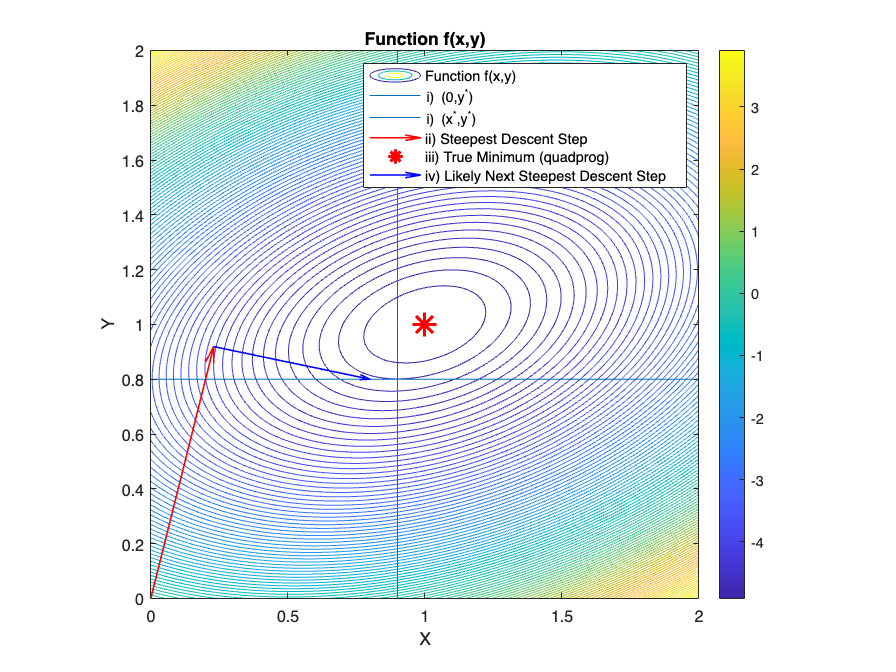

x=linspace(0,2,100);
y=linspace(0,2,100);
[X,Y]=meshgrid(x,y);

Z = nonlin_fun(X,Y);

contour(X,Y,Z,100); axis equal; colorbar; title('Function f(x,y)')
hold on

% overlay direction of gradient from starting point
p1 = [0 0];                        
p2 = [136/592 544/592];                         
dp = p2-p1;    

% likely next steepest descent step (guess from graph)
p3 = p2;                        
p4 = [0.8 0.8];                         
dp2 = p4-p3;    
        

% overlay parts i,ii,iii
line([0 2],[0.8 0.8])
line([0.9 0.9],[0 2])
quiver(p1(1),p1(2),dp(1),dp(2),0,LineWidth=1,Color='red')
plot([solution(1)],'o','Marker','*','Color','red','MarkerSize',15,'LineWidth',2)
quiver(p3(1),p3(2),dp2(1),dp2(2),0,LineWidth=1,Color='blue')


legend('Function f(x,y)','i) (0,y^*)','i) (x^*,y^*)','ii) Steepest Descent Step','iii) True Minimum (quadprog)','iv) Likely Next Steepest Descent Step')
xlabel('X')
ylabel('Y')

hold off

### Discussion

Parts i) demonstrate the two lines where at first x is frozen at x=0 to find optimal y, then y is frozen at that value to find optimal x. You can see from the contours that both lines appear at a 1D minimum along the other variable. This is not a very accurate method of obtaining a true local minimum but does provide an estimate that is not too far off.

ii) shows the first step of the gradient descent algorithm where the steepest downhill at (0,0) is followed to its minimum (when it starts going up hill) that is the end of the first step. As shown in iv) I have estimated the next step of the algorithm as a movement along the steepest downhill from the previous point to a minimum in 1D. This will continue until the true minimum is reached.

iii) shows the true solution as given by quadprog. 